answersOn = true;

%  Units
ONE.kOhm = 1e3;
ONE.pF = 1e-12;
ONE.kHz = 1e3;
ONE.MHz = 1e6;
ONE.GHz = 1e9;
ONE.nH = 1e-9;
ONE.uH = 1e-6;
ONE.uF = 1e-6;
ONE.uSec = 1e-6;
ONE.mSec = 1e-3;
ONE.uV = 1e-6;
ONE.mV = 1e-3;
ONE.mW = 1e-3;

clearvars -except answersOn ONE

# Digital Signal Processing Homework 08 -- Butterworth and Chebyshev Filters using MATLAB

Reading -- Review Chapter 19 and 20 on Recursive Filters and Chebyshev Filters

### Problem 1

Design a 5 pole IIR Chebyshev lowpass filter with 1 dB of ripple that has a corner frequency of 12 BPM using a sample rate of 600 BPM.  Compute the filter coefficients using the MATLAB low pass filter design tool.

You can get the coefficients of the filter after running the script by looking at the values of a and b displayed for the Direct Form of the IIR fr easy copy to MATLAB.  Copy the values for variables a and b  (see example ouput from MATLAB function below)

The numerator coefficients are saved in the b variable and the denominator coefficients in the a varialble.  This is opposite of how the text labels the numberator and denominator coefficients.

Part A 

Copy the values from the command window into this Live script and then use the impz and freqz functions to compute the impulse and frequency responses respectively.  Compute 512 points for each response.

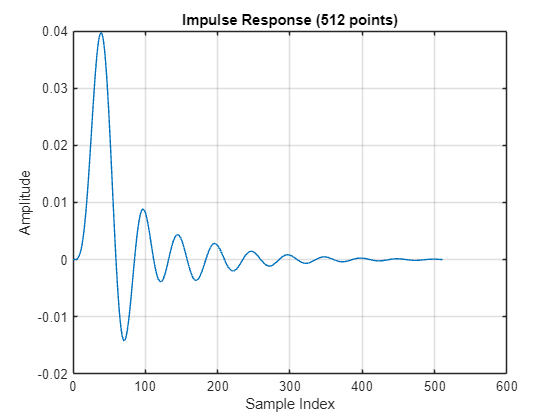


clearvars -except answersOn ONE



% num = b;
% den = a;


%  Find the impulse response using the impz function



%  Find the frequency response.  Results in two return variables.  The
%  first is the frequency response (complex) and the second is a vector of
%  frequencies from 0 to pi.  Pi is 1/2 of the sample rate

%  Put your solution here
b = [0.0000001, 0.0000006, 0.0000011, 0.0000011, 0.0000006, 0.0000001];
a = [1.0000000, -4.8628843, 9.4795648, -9.2592853, 4.5315589, -0.8889505];
N = 512;
[h, t] = impz(b, a, N);
figure;
plot(t, h); grid on;
xlabel('Sample Index'); ylabel('Amplitude');
title('Impulse Response (512 points)');

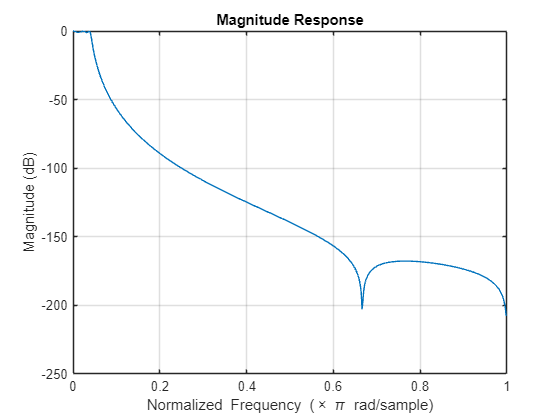

[H, w] = freqz(b, a, N);
figure;
plot(w/pi, 20*log10(abs(H))); 
xlabel('Normalized Frequency (\times \pi rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response');
grid on;

Part B

Using MATLAB create a normally distributed random noise sequence of length 32768.  Use the randn( 32768, 1)  function to create a column vector of length 32768 of random numbers.  In the sample domain, convolve the random noise sequence with the impulse response of the filter.  What will be the length of the convolution output?

The result of the convoluton will have end effects at the begining and at the end.  Which samples of the output of the convolution are valid, that is which  samples have no end effects?  Think about the length of the impulse response and how many samples would have to enter the system so that the impulse response would be multiplied by valid input values.

Plot the input noise and the output of the convolution, the filtered noise.

Plot the frequency spectrum of the noise using the FFT.

What do you notice about the frequency spectrum of the noise?

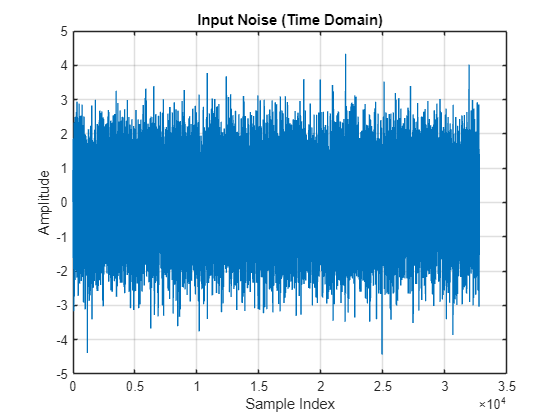

%  The length of the convolution is M+N-1 where M is the length of the
%  input sequence (32768), N is the length of the impulse response (512).
%  Then the length of the convolution is M+N-1 = 32768 + 512-1 = 33279
%


%  The convlution will have N-1 values that are part of the end effects of
%  the covolution.  Therefore valid samples are from sample 512 to 32768

%  Create a noise vector of length 32768



%  Convolve the noise sequence with the impulse response

%  Put your solution here
M = 32768;
noiseIn = randn(M,1);
convOut = conv(noiseIn, h);
L = length(convOut);  % Should be 32768 + 512 - 1 = 33279
figure;
plot(noiseIn); grid on;
xlabel('Sample Index'); ylabel('Amplitude');
title('Input Noise (Time Domain)');

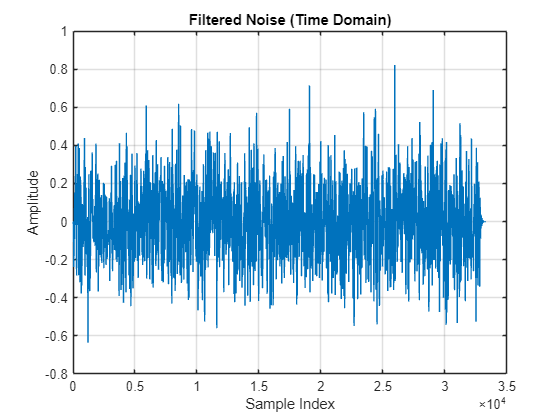

figure;
plot(convOut);
xlabel('Sample Index'); ylabel('Amplitude');
title('Filtered Noise (Time Domain)'); grid on;

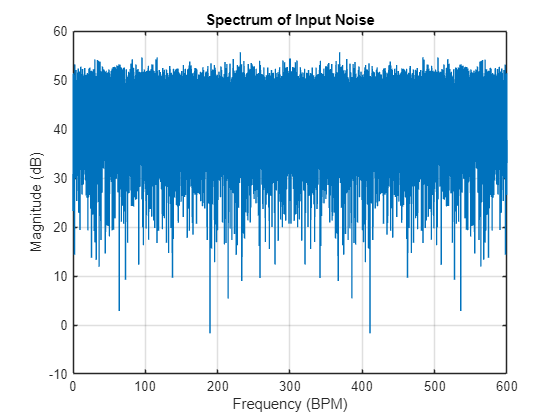

NFFT = 32768;
X_in = fft(noiseIn, NFFT);
X_out = fft(convOut, NFFT);
f_axis = (0 : NFFT-1)*(600/NFFT);
figure;
plot(f_axis, 20*log10(abs(X_in)));
xlabel('Frequency (BPM)'); ylabel('Magnitude (dB)');
title('Spectrum of Input Noise'); grid on;

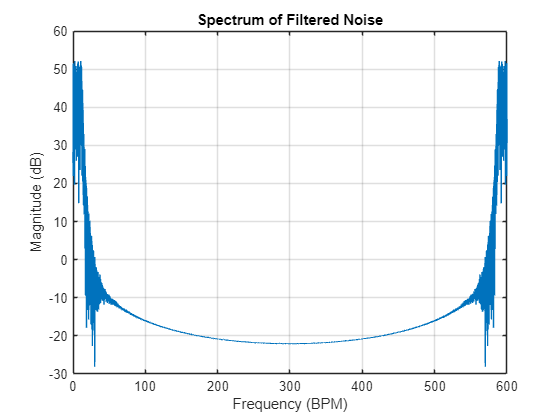

figure;
plot(f_axis, 20*log10(abs(X_out)));
xlabel('Frequency (BPM)'); ylabel('Magnitude (dB)');
title('Spectrum of Filtered Noise'); grid on;

### Problem 2

A filter has the following impulse response of length 11.

h = 0.0000000 ,0.0398999 ,0.0860792 ,0.1291187 ,0.1595995 ,0.1706054 ,0.1595995 ,0.1291187 ,0.0860792 ,0.0398999 ,0.0000000

Plot the frequency response of the filter with this impulse response assuming a sampling frequency of 8 kHz.

Generate a signal that consists of two sinusoids.  One is 300 Hz with and the other 3kHz.  Each has a length of 1014 samples.  A sinusoid with frequency "freq" can be created in MATLAB using where "freq" is the sinusoid frequency and "sampleFreq" is the sampling frequency

Then add the two signals together.

Convolve the combined signal with the impulse reponse of the filter using Frequency Domain convolution.  Remember to pad each sequence to the length of the output convolution.

Plot the resulting time domain signal.  Plot the frequency spectrum of the signal before filtering and after filtering

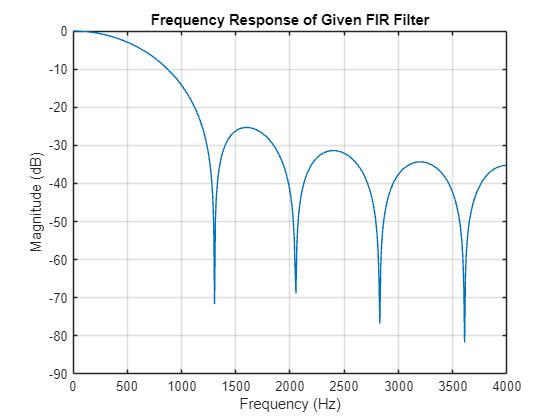

clearvars -except answersOn ONE

%  Impulse response of the filter

impResp = [ 0.0000000 ,0.0398999 ,0.0860792 ,0.1291187 ,0.1595995 ,0.1706054 ,0.1595995 ,0.1291187 ,0.0860792 ,0.0398999 ,0.0000000];

%  Put your solution here
fs = 8000;
N = 512;
[H, w] = freqz(impResp, 1, N, fs);
figure;
plot(w, 20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Given FIR Filter');
grid on;

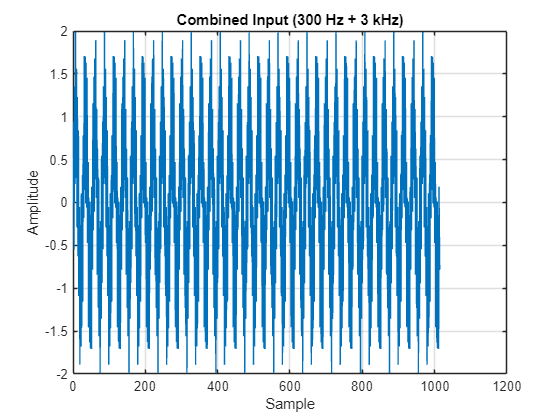

L = 1014;
n = (0:L-1).';
fs = 8000;          % 8 kHz sampling

% Create two sinusoids
x1 = sin(2*pi*300/fs * n);
x2 = sin(2*pi*3000/fs * n);

% Combine the two signals
x = x1 + x2;
h = impResp(:);             % Column vector
Nconv = L + length(h) - 1;  % Output length

% Zero-pad both
X = fft(x, Nconv);
H = fft(h, Nconv);

YfreqDomain = X .* H;       % Multiply in frequency domain
y = ifft(YfreqDomain);      % Convolution result

% Real part (any numerical imag due to round-off)
y = real(y);
figure;
plot(x);
xlabel('Sample'); ylabel('Amplitude');
title('Combined Input (300 Hz + 3 kHz)'); grid on;

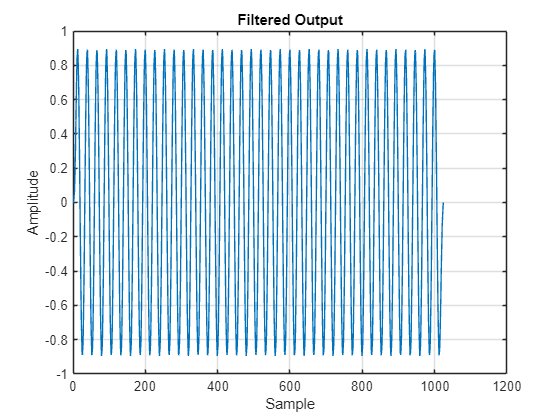

figure;
plot(y);
xlabel('Sample'); ylabel('Amplitude');
title('Filtered Output'); grid on;

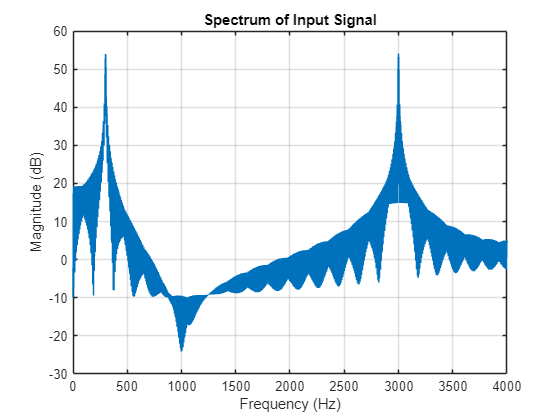

NFFT = 4096;  % some convenient FFT size
X_input = fft(x, NFFT);
Y_output = fft(y, NFFT);
f_axis = (0:NFFT-1)*(fs/NFFT);

figure;
plot(f_axis, 20*log10(abs(X_input)));
xlim([0 fs/2]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectrum of Input Signal'); grid on;

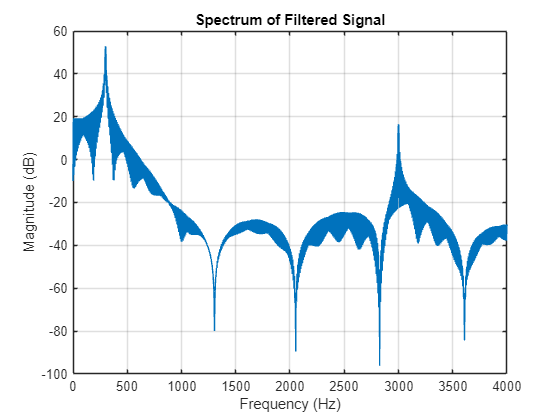

figure;
plot(f_axis, 20*log10(abs(Y_output)));
xlim([0 fs/2]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectrum of Filtered Signal'); grid on;